Multi-Fidelity GP model

Takes a list of GPs as an input and a mean function and a kernel object

clear all
close all
clc

A = 0.5; B = 10; C = -5;
ff{1} = @(x) (6*x-2).^2.*sin(12*x-4);
ff{2} = @(x) 0.4*ff{1}(x)-x-1;
ff{3} = @(x) A*ff{1}(x)+B*(x-0.5)-C; 

xx = linspace(0,1,100)';
yy = ff{1}(xx);


x{1} = [0;0.75;1];
y{1} = ff{1}(x{1});

for i = 2:3
x{i} = [x{i-1}; lhsdesign(5,1)];
y{i} = ff{i}(x{i});
end

ma = means.linear(4) + means.const(1);
mb = means.linear(2);

a = kernels.Matern52(1,0.2);
b = kernels.EQ(1,0.3);

for i = 1:3
    Z{i} = GP(mb,b);
    Z{i} = Z{i}|[x{i} y{i}];
    Z{i} = Z{i}.train;
end

MF = MFGP(Z,ma,a);

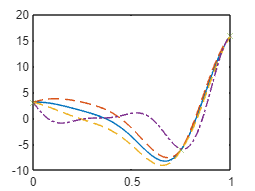

[ys,sig] = Z{1}.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x{1},y{1},'x')

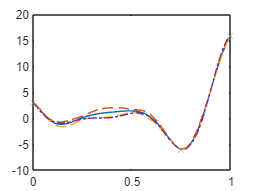

[ys,sig] = MF.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x{1},y{1},'x')

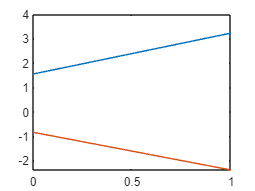

ym2 = MF.Zd{2}.mean.eval(xx);
ym3 = MF.Zd{3}.mean.eval(xx);

figure
plot(xx,ym2)
hold on
plot(xx,ym3)

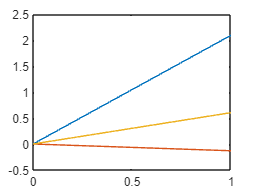


ym1 = MF.GPs{1}.mean.eval(xx);
ym2 = MF.GPs{2}.mean.eval(xx);
ym3 = MF.GPs{3}.mean.eval(xx);


figure
plot(xx,ym1)
hold on
plot(xx,ym2)
plot(xx,ym3)

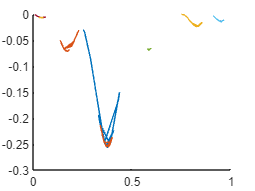

figure
hold on
tic
for i = 1:10
    [xn{i},Fxn{i},xvn{i},fvn{i}] = VSGD(@(x) MF.eval_var(x),rand(),'lr',0.1,'lb',0,'ub',1,'gamma',0.1,'iters',2000,'tol',1*10^(-4));
    plot(xvn{i},fvn{i})
end

toc

Elapsed time is 4.849114 seconds.
